% Build Color Matricies
desiredSize = [512 512];
black3DArray = fnBuildCDataFromConstantColor([0.0 0.0 0.0], desiredSize);
darkgrey3DArray = fnBuildCDataFromConstantColor([0.3 0.3 0.3], desiredSize);
lightgrey3DArray = fnBuildCDataFromConstantColor([0.6 0.6 0.6], desiredSize);

red3DArray = fnBuildCDataFromConstantColor([1.0 0.0 0.0], desiredSize);
green3DArray = fnBuildCDataFromConstantColor([0.0 1.0 0.0], desiredSize);
blue3DArray = fnBuildCDataFromConstantColor([0.0 0.0 1.0], desiredSize);

colorsArray = {darkgrey3DArray, black3DArray, red3DArray, green3DArray, blue3DArray};

% tempConjunctionMask = logical(final_data_explorer_obj.amalgamationMasks.AlphaConjunctionMask);

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
    temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.Edge(i,:,:));
    temp.curr_edge_mask = temp.curr_edge_mask + squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:));
    
    
    im = image('CData', temp.curr_edge_mask, 'AlphaData', temp.curr_edge_mask);
%     im.AlphaData = 0.5;
end


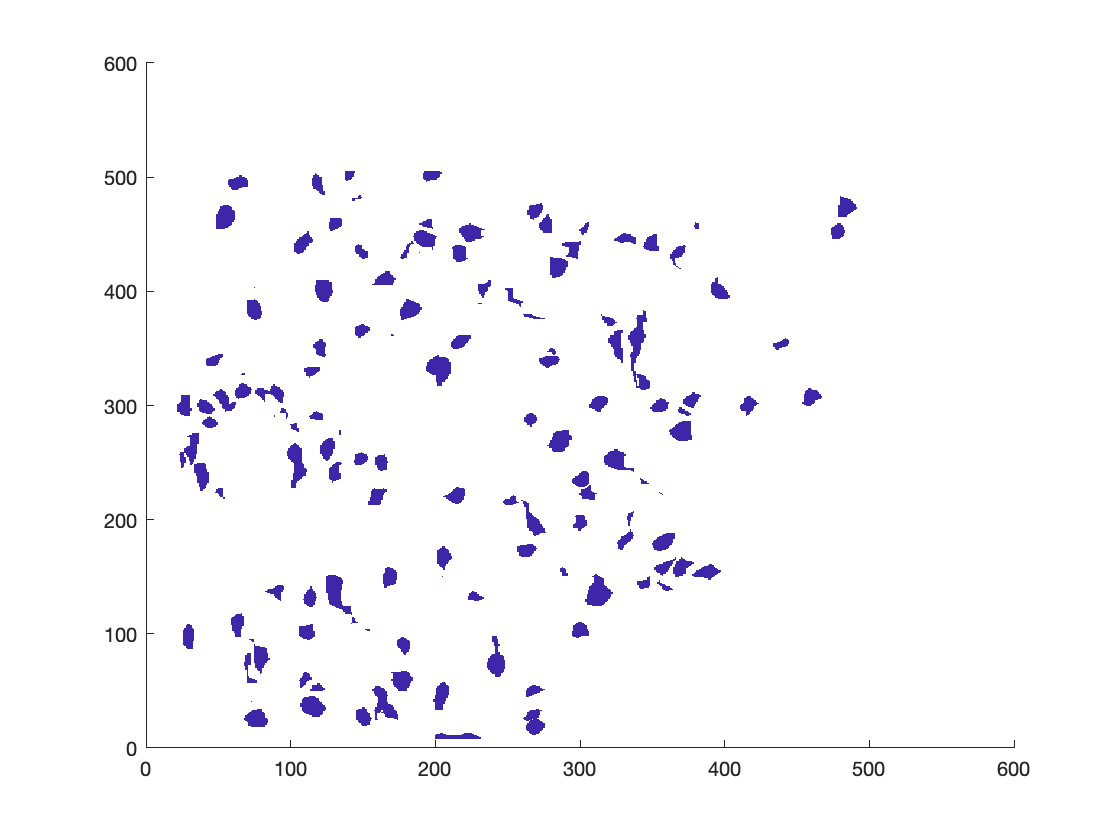

figure
clf
% hold on
for i = 1:final_data_explorer_obj.num_cellROIs
%     temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge0(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
%     temp.curr_edge_mask = squeeze(final_data_explorer_obj.roiMasks.OutsetEdge2(i,:,:)); % OutsetEdge0: accidentally includes inside (fill) as well.
    temp.curr_fill_mask = final_data_explorer_obj.getFillRoiMask(i);
%     temp.curr_edgePlotRegionMask = temp.curr_fill_mask - final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i);
temp.curr_edgePlotRegionMask = final_data_explorer_obj.getEdgeOffsetRoiMasks(-2, i);
%     temp.curr_edgePlotRegionMask = final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i) - final_data_explorer_obj.getEdgeOffsetRoiMasks(-2, i);
%     temp.curr_edgePlotRegionMask = temp.curr_fill_mask - final_data_explorer_obj.getEdgeOffsetRoiMasks(-1, i);

    im = image('CData', temp.curr_edgePlotRegionMask, 'AlphaData', temp.curr_edgePlotRegionMask);
end

outsetsFig = figure
clf(outsetsFig)

offsetIndicies = [nan, 0, 1, 2, 3];

for i = 1:final_data_explorer_obj.num_cellROIs
    cellROIIdentifier.uniqueRoiIndex = i;
    cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
    
    im(1) = image('CData', darkgrey3DArray, 'AlphaData', squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:)));
    im(2) = image('CData', black3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(0, i));
    im(3) = image('CData', red3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(1, i));
    im(4) = image('CData', green3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(2, i));
    im(5) = image('CData', blue3DArray, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(3, i));
    
    for plotImageIndex = 1:length(im)
        currEdgePlotImageIdentifier.cellROIIdentifier = cellROIIdentifier;
        currEdgePlotImageIdentifier.edgeOffsetIndex = offsetIndicies(plotImageIndex);
        set(im(plotImageIndex), 'UserData', currEdgePlotImageIdentifier);
        
        if isnan(currEdgePlotImageIdentifier.edgeOffsetIndex)
            % For the fill layer, the edgeOffsetIndex is nan
            curr_tag_string = sprintf('%d_%s_fill', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName);
        else
            curr_tag_string = sprintf('%d_%s_edgeOffsetIndex_%d', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName, offsetIndicies(plotImageIndex));
        end
        
%         curr_tag_string = getCellRoiPlotTagString(offsetIndicies(plotImageIndex), cellROIIdentifier);
        set(im(plotImageIndex), 'Tag', curr_tag_string);
        
    end

end
title('Outsets')
set(gca,'xtick',[],'YTick',[])

%% Insets:
insetsFig = figure
clf(insetsFig)
insetIndicies = [nan, 0, -1, -2, -3];



for i = 1:final_data_explorer_obj.num_cellROIs
    cellROIIdentifier.uniqueRoiIndex = i;
    cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
    
    for plotImageIndex = 1:length(im)
        currEdgePlotImageIdentifier.cellROIIdentifier = cellROIIdentifier;
        currEdgePlotImageIdentifier.edgeOffsetIndex = insetIndicies(plotImageIndex);
        
        if isnan(currEdgePlotImageIdentifier.edgeOffsetIndex)
            % For the fill layer, the edgeOffsetIndex is nan
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', squeeze(final_data_explorer_obj.roiMasks.Fill(i,:,:)));
            curr_tag_string = sprintf('%d_%s_fill', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName);
        else
            im(plotImageIndex) = image('CData', colorsArray{plotImageIndex}, 'AlphaData', final_data_explorer_obj.getEdgeOffsetRoiMasks(currEdgePlotImageIdentifier.edgeOffsetIndex, i));
            curr_tag_string = sprintf('%d_%s_edgeOffsetIndex_%d', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName, offsetIndicies(plotImageIndex));
        end
        
        set(im(plotImageIndex), 'UserData', currEdgePlotImageIdentifier);
%         curr_tag_string = getCellRoiPlotTagString(offsetIndicies(plotImageIndex), cellROIIdentifier);
        set(im(plotImageIndex), 'Tag', curr_tag_string);
        
    end

end
title('Insets')
set(gca,'xtick',[],'YTick',[])

function [plotString] = getCellRoiPlotTagString(offsetIndex, cellROIIdentifier)
%     cellROIIdentifier.uniqueRoiIndex = i;
%     cellROIIdentifier.roiName = final_data_explorer_obj.cellROIIndex_mapper.getRoiNameFromUniqueCompIndex(i);
%   
    plotString = sprintf('%d_%s_edgeOffsetIndex_%d', cellROIIdentifier.uniqueRoiIndex, cellROIIdentifier.roiName, offsetIndex);
    
end